%CLEAR THE WORKSPACE

clear all;
clc;

% Ranges of parameters to investigate how peak of infected population I varies

tR_range = 0:0.1:1;
vR_range = 0:0.1:1;

% Time range to solve

tspan = 0:0.01:100;

% Initial conditions

init_cond = [0.95 .05 0 0 0]';

% Matrix to store peak I values

I_peak = zeros(length(tR_range),length(vR_range));

%Nested for loop to run tR for different vR

for tR_ind = 1:length(tR_range)

 
    for vR_ind = 1:length(vR_range)
        
        params = [vR_range(vR_ind), tR_range(tR_ind), 0.8, 0.143, 0.0238, 0.143, 0.016, 0.143]; %param values
        
        [T, S, I1u, I1a, I2, R] = covidsolver2(params, init_cond, tspan, 0, 0); %run covidsolver for the given tR and vR values
        I = I1u + I1a + I2; %Calculate total infected
        
        I_peak(tR_ind, vR_ind) = max(I); %Store max value for the given tR and vR values
        
    end
end

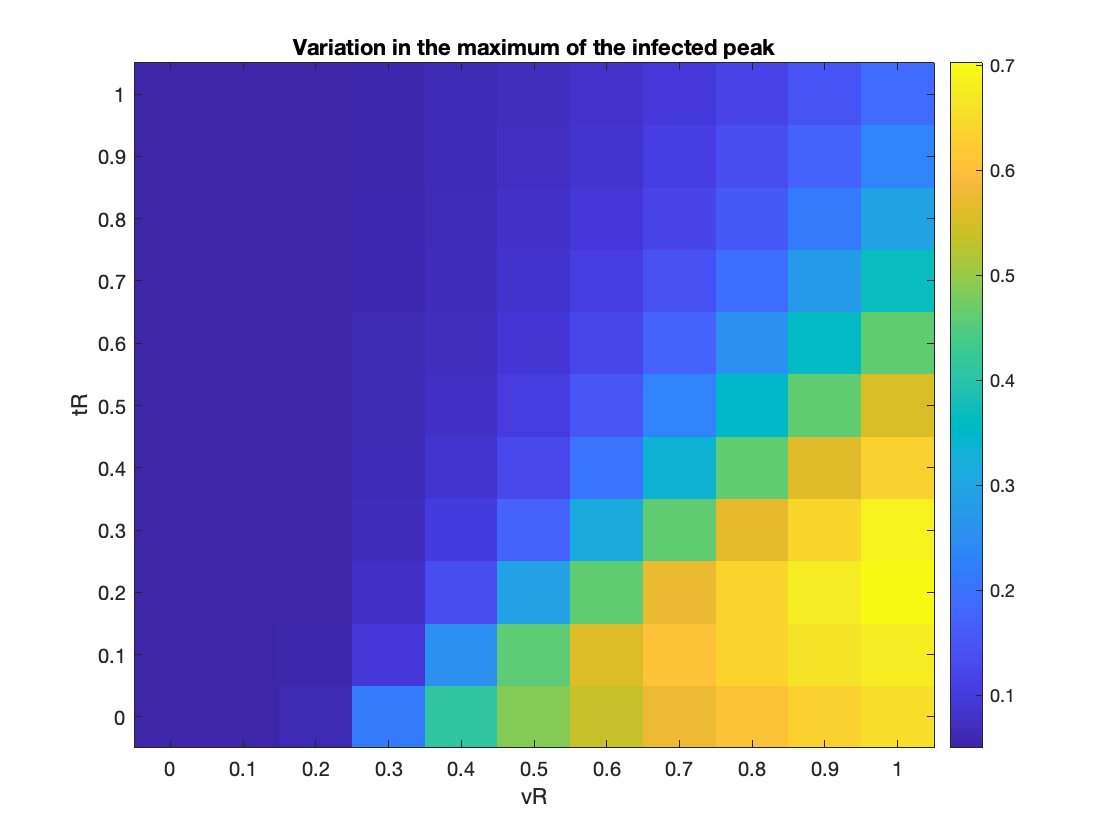

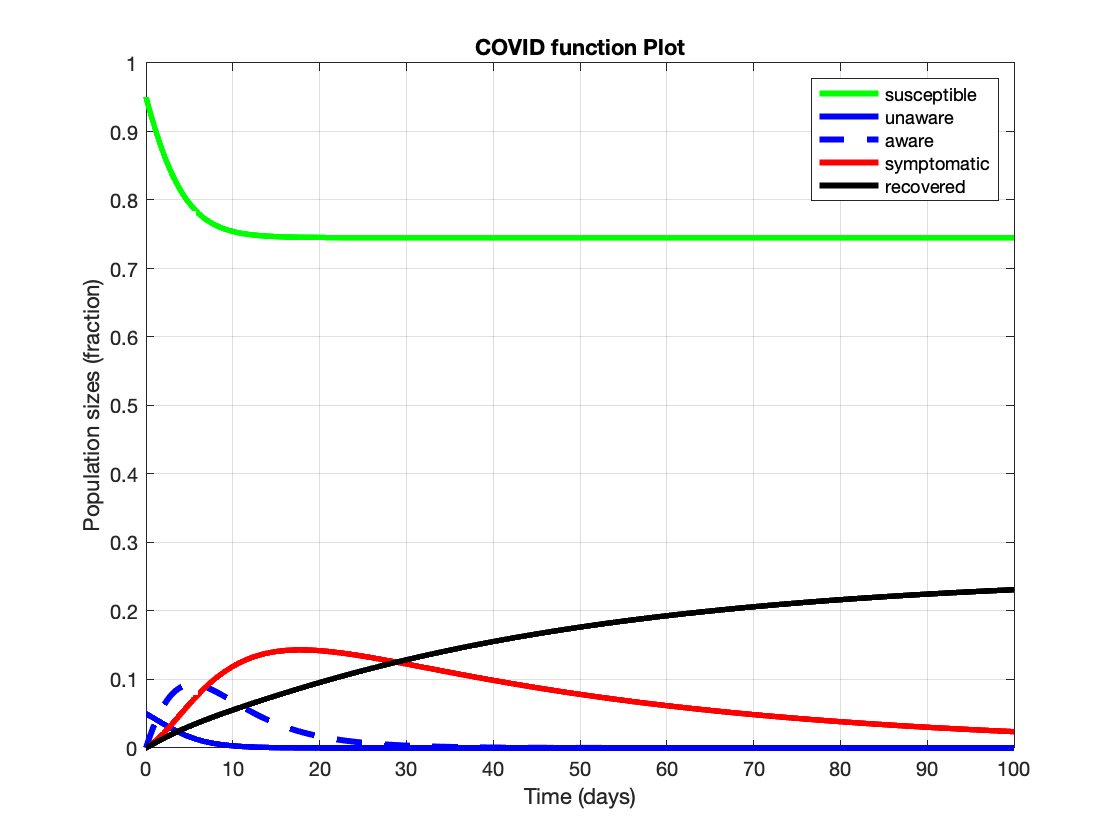


% Plot how I_peak varies for the tR and vR tested